# Classify Age of Brain MRI Study Participants using Deep Learning

This example shows how to apply transfer learning to tune a pretrained deep neural network (ResNet-18) to perform chronological age classification on a brain MRI dataset.

The study dataset contains 3D brain volumes and demographic data obtained from 155 study participants. To illustrate transfer learning using a lightweight deep network model (ResNet-18) pretrained with 2D image data, this example employs 2D axial midslice images extracted from each of the 3D volumes. It shows how ResNet-18 can be retrained to accurately classify these 2D brain images into three age group categories:

- Participants Aged 3-5

- Participants Aged 7-12

- Participants Aged 18 or older, classified as Adults  

## Read OpenNEURO Dataset 

mriRootDataFolder = 'ds000228-1.1.0-subset';
mriDataFolder = fullfile(mriRootDataFolder, 'derivatives', 'preprocessed_data');

### Read 3D Volumetric Data

**Read Neuroimaging (NIfTI) Image File** 

vol = niftiread(fullfile(mriDataFolder,"sub-pixar001","sub-pixar001_normed_anat.nii.gz"));

**Visualize Skull-Stripped Volume**

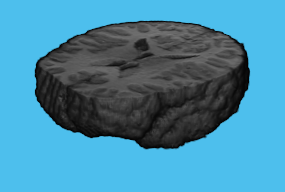

mask = niftiread(fullfile(mriDataFolder,"sub-pixar001","sub-pixar001_analysis_mask.nii.gz"));
vol = int16(vol) .* int16(mask); % Apply skull-stripping 
numSlices = size(vol,3);
imshow(vol(:,:,round(numSlices/2)));
volshow(vol(:,:,1:round(numSlices/2)),'CameraViewAngle',7.5);

### Read Participant Data

**Read Tabular Data**

participantFilename = fullfile(mriRootDataFolder, 'participants.tsv');
participantData = readtable(participantFilename,'FileType','delimitedtext','VariableNamingRule','preserve');
head(participantData) % view the first entries in the participant table to illustrate the original dataset contents

ans = 8×19 table
     participant_id      Age      AgeGroup    Child_Adult    Gender    Handedness    ToM Booklet-Matched    ToM Booklet-Matched-NOFB    FB_Composite    FB_Group    WPPSI BD raw    WPPSI BD scaled    KBIT_raw    KBIT_standard    DCCS Summary    Scanlog: Scanner    Scanlog: Coil     Scanlog: Voxel slize    Scanlog: Slice Gap
    ________________    ______    ________    ___________    ______    __________    ___________________    ________________________    ____________    ________    <

**View Summary Statistics**

participantData.AgeClass(participantData.Age >= 3 & participantData.Age < 6) = categorical("Ages3-5");
participantData.AgeClass(participantData.Age >= 7 & participantData.Age < 13) = categorical("Ages7-12");
participantData.AgeClass(participantData.Age >= 18) = categorical("Adults");

summary(participantData.AgeClass)

     Ages3-5       65 
     Ages7-12      57 
     Adults        33 


The dataset of 155 participants includes 65 children in the ages 3-5 class, 57 children in the ages 7-12 class, and 33 adults.

### Read 2D Image Data

**Extract Axial Slice Exemplars**

exemplars = prepare2DImageDataset(mriDataFolder);

**View Axial Slices by Age Class**

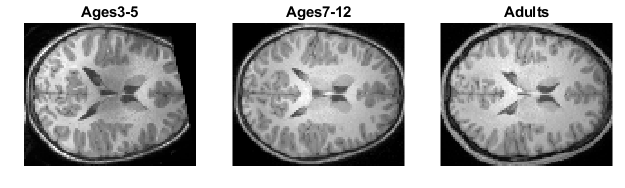

ageClasses = string(categories(participantData.AgeClass));

figure('Position',[10 10 500 150]);
tiledlayout(1,numel(ageClasses),'Padding','none','TileSpacing','none');

for ii=1:length(ageClasses)
    nexttile;
    imshow(mat2gray(exemplars{ii}));
    title(ageClasses((ii)));
end

## Prepare Dataset for Deep Learning

### Extract, Normalize, and Augment 2D MRI Images

classifierDataFolder = ['2DImageSet_' datestr(datevec(now),30)];
applySkullStripping = true;
applyAugmentation = true;

Call `prepare2DImageDataset `with the specified options to create a 2D image set folder: 

prepare2DImageDataset(mriDataFolder, classifierDataFolder, applyAugmentation, applySkullStripping);

### Create Image Datastore and Visualize Images

mriImgds = imageDatastore(classifierDataFolder,'IncludeSubfolders',true,'LabelSource','foldernames','FileExtensions','.png');

`The shuffle` method for an` imageDatastore `object can be used to select a random image from each image class (age group):

mriImgdsRand = shuffle(mriImgds);
mriImgdsExamples = splitEachLabel(mriImgdsRand,int16(1)); % Select the firstmost image from the just-shuffled datastore for each age class
numLabels = length(mriImgdsExamples.Labels);

for ii=numLabels:-1:1
    [imgArray{ii},infoArray(ii)] = readimage(mriImgdsExamples,ii);
end

We can display these random selections from each age class to see how they compare side-by-side:

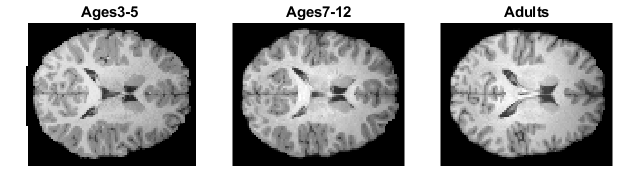

figure('Position',[10 10 500 150]);
tiledlayout(1,3,'Padding','none','TileSpacing','none');
for selCount=1:length(ageClasses)
    % Find the random-selected image in imageArray which pertains to the next age class for display
    idx = find(ageClasses(selCount) == [infoArray.Label]);
    
    % If image is a flipped image (from the offline data augmentation), then flip it back, so all images have the same orientation
    [~,fname] = fileparts(infoArray(idx).Filename);
    if startsWith(fname,'image2')
        img = imrotate(imgArray{idx},-180);
    else
        img = imgArray{idx};
    end
    
    % Show the random selected image for the next age class
    nexttile;
    imshow(mat2gray(img));
    title(infoArray(idx).Label);
end

### Divide the Dataset for Training and Evaluation

Training a neural network requires the dataset be split between the:

- Training image set, to supply the network with images to learn the classification task during training

- Validation image set, to test the network's classification accuracy during training (online)

- Test image set, to test the network's classification accuracy and evaluate the network performance after training is completed (offline) 

[trainImgs,testImgs] = splitEachLabel(mriImgds,0.85,'randomized'); % Reserve 15 percent of overall dataset for testing

The training image set is then further subdivided to reserve a portion for validation:

[trainImgs, valImgs] = splitEachLabel(trainImgs,0.8,'randomized'); % Reserve 20 percent of dataset available for training for online validation

## Train ResNet-18 for Brain Age Classification

### Load the Pretrained Network

ResNet-18 is a convolutional neural network that is trained on more than a million 2D color images from the ImageNet database.The network is 18 layers deep and can classify images into 1000 distinctive object categories, such as keyboard, mouse, pencil, and many animals. This network was not trained on any brain images nor for the task of discriminating ages among normalized brain MRI images.

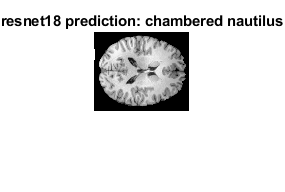

netName = 'resnet18';
net = resnet18();

netInputSize = net.Layers(1).InputSize;
inputImageSize = netInputSize(1:2);

img = imread(fullfile(classifierDataFolder, 'Adults', 'image_033.png'));
imgLabel = classify(net, imresize(img, inputImageSize)); % resize 2D brain image to match network's input image size

figure('Position',[10 10 200 200]);
imshow(img);
title([netName ' prediction: ' char(imgLabel)]);

### Prepare Network for Transfer Learning

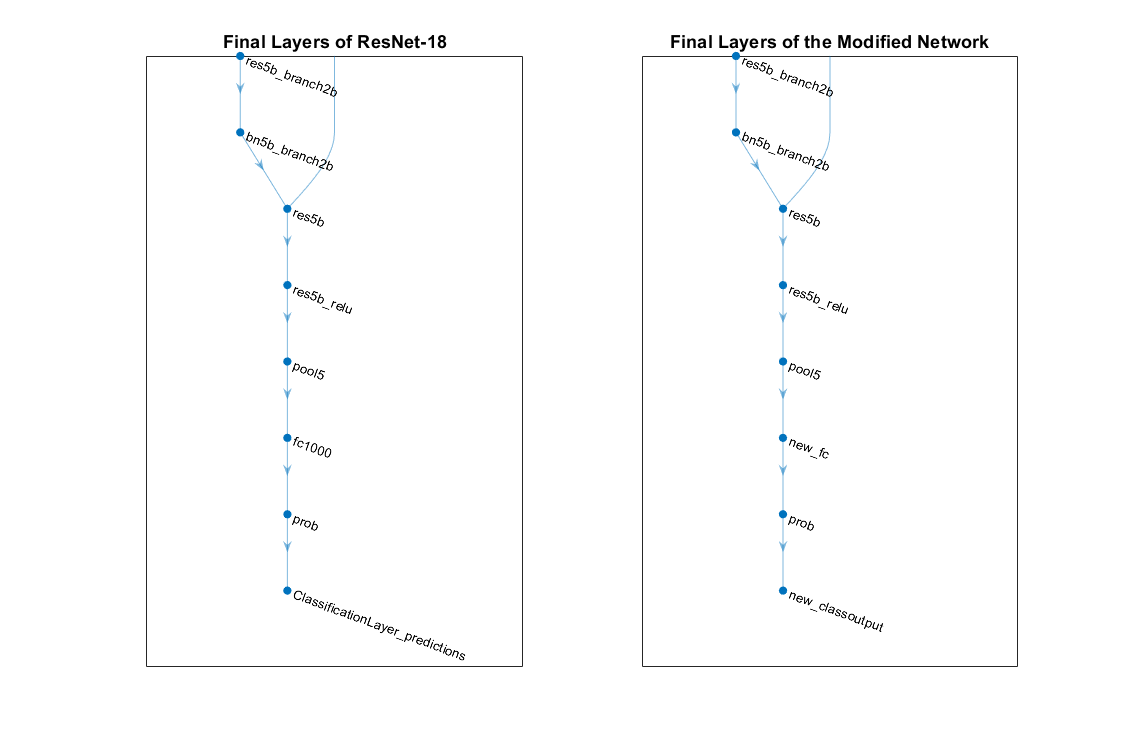

lgraph = layerGraph(net);
numClasses = numel(categories(mriImgds.Labels));

newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',newClassLayer);

figure("Position",[10 10 900 600])
subplot(1,2,1)
plot(layerGraph(net))
xlim ([0 4]);ylim([0 8])
title('Final Layers of ResNet-18')
subplot(1,2,2)
plot(lgraph)
xlim ([0 4]);ylim([0 8])
title('Final Layers of the Modified Network')

### Resize Images and Apply Online Augmentation

net = resnet18();
imageSize = net.Layers(1).InputSize(1:2);
imageAugmenter      = imageDataAugmenter('RandRotation',[-30,30]); % Use randomized rotation for further data augmentation

datastore_train     = augmentedImageDatastore(imageSize,trainImgs,'DataAugmentation',imageAugmenter);
datastore_validate  = augmentedImageDatastore(imageSize,valImgs);
datastore_test      = augmentedImageDatastore(imageSize,testImgs);

disp(table({'Train';'Validate';'Test'},[datastore_train.NumObservations;datastore_validate.NumObservations;datastore_test.NumObservations],'VariableNames',{'Datastore','Image Count'}))

     Datastore      Image Count
    ____________    ___________

    {'Train'   }        212    
    {'Validate'}         52    
    {'Test'    }         46    



### Specify Training Options for Transfer Learning

trainOpts.initLearnRate   = 0.001; % 10x reduction in initial learning rate
trainOpts.valFrequency    = 4; 
trainOpts.miniBatchSize   = floor(numel(datastore_train.Files)/trainOpts.valFrequency); % rounding needed in case offline data augmentation is disabled 

To speed the training demonstration for this example, the number of epochs will be reduced by 2x:

trainOpts.maxEpochs       = 15;

The  trainingOptions function creates and returns a training options object based on these parameters:   

options = trainingOptions('sgdm', ...
    'MiniBatchSize',trainOpts.miniBatchSize, ...
    'MaxEpochs',trainOpts.maxEpochs, ...
    'InitialLearnRate',trainOpts.initLearnRate, ...
    'Shuffle','every-epoch', ... % this handles the case where the mini-batch size doesn't evenly divide the number of training images
    'ValidationData',datastore_validate, ... % source of validation data to evaluate learning during training
    'ValidationFrequency',trainOpts.valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress'); % display a plot of progress during training

### Train the Network

if canUseGPU()
    gpudev = gpuDevice; % Use the default GPU device, if there's more than one
    reset(gpudev);
end

Train the network with the training image set.  

[mriNet,~] = trainNetwork(datastore_train, lgraph, options);

## Perform Brain Age Classification with Trained Network

Classify the test dataset images using the trained network: 

[test_preds,test_scores] = classify(mriNet,datastore_test);

### Determine Network Accuracy

accuracy = mean(test_preds == testImgs.Labels)

accuracy = 0.9783

### Compute Confusion Matrix

Use a [`confusionchart`](https://www.mathworks.com/help/deeplearning/ref/confusionchart.html) to create a confusion matrix identifying which label were correctly predicted. This can help to identify where the network struggles the most within the test image set.

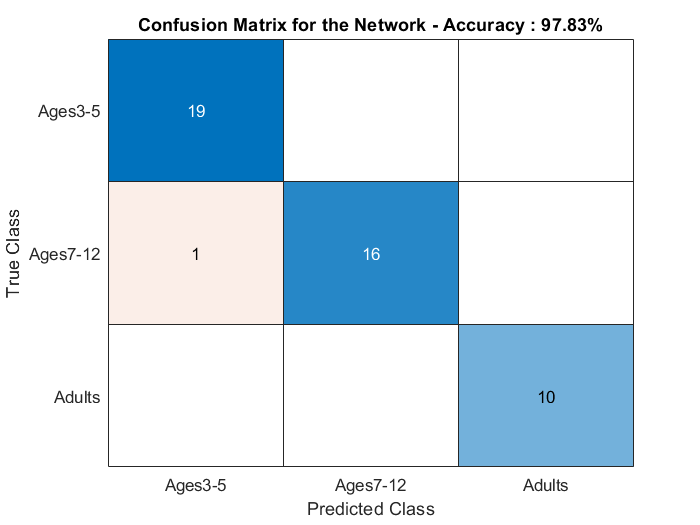

figure;
cm = confusionchart(testImgs.Labels,test_preds);
sortClasses(cm,["Ages3-5","Ages7-12","Adults"])
cm.Title = ['Confusion Matrix for the Network - Accuracy : ' num2str(100*round(accuracy,4)) '%'];

## Evaluate the Trained Network

### Visualize Features Used by Network via Occlusion

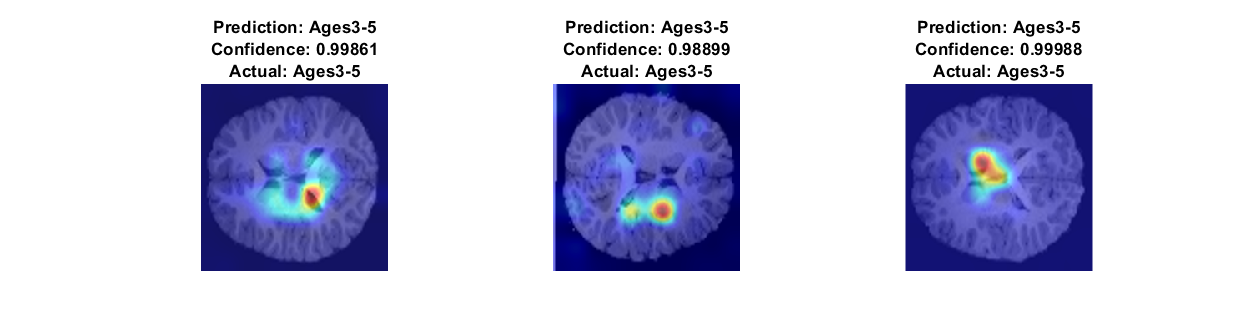

viewOcclusionSensitivityMaps("Ages3-5",3, mriNet, testImgs, test_preds, test_scores);

For comparison, the occlusion sensitivity maps can also be visualized for the two older age classes:

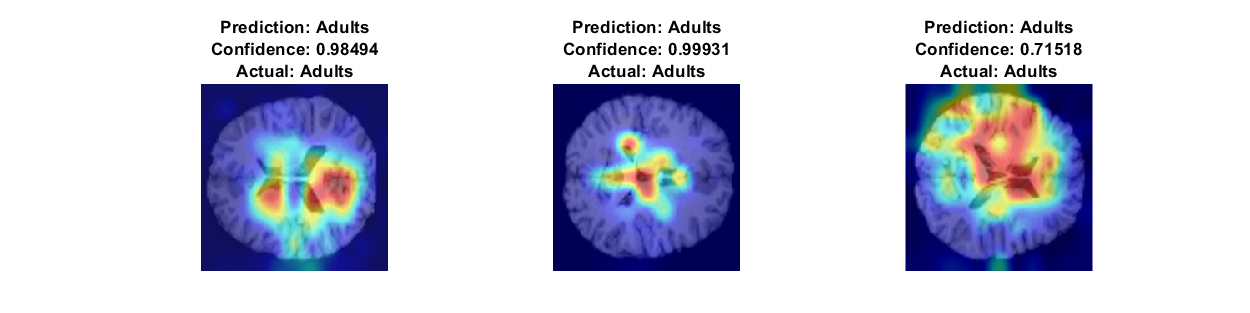

ageClass = categorical("Adults");
numSelections = 3;
viewOcclusionSensitivityMaps(ageClass,numSelections, mriNet, testImgs, test_preds, test_scores);

## Helper Functions

function viewOcclusionSensitivityMaps(ageClass,nSelections, mriNet, testImgs, test_preds, test_scores)

figure("Position",[10 10 1000 250])

netInputSize = mriNet.Layers(1).InputSize;
inputImageSize = netInputSize(1:2);

% Create a randomized set of indices into the test image datastore
selectionIdxs = randperm(length(testImgs.Files));

% Visualize a random selection of correctly predicted images for each age class
tiledlayout('flow'); % up to 5 selections per row

selCount = 1;
mapCount = 1;
while mapCount <= nSelections
    selIdx = selectionIdxs(selCount); % A randomly-selected image in the test image set
    currLabel = testImgs.Labels(selIdx);
    
    if currLabel == ageClass && currLabel == test_preds(selIdx) % Selected image is of the specified age class and has been correctly classified
        img = imresize(testImgs.readimage(selIdx),inputImageSize);
        scoreMap = occlusionSensitivity(mriNet, img, test_preds(selIdx));
        
        nexttile;
        imshow(img);
        hold on
        imagesc(scoreMap,'AlphaData',0.5); % Overlay the score map onto the image with transparency
        
        colormap jet
        title([ ...
            "Prediction: " + string(test_preds(selIdx)) ,...
            "Confidence: " + num2str(max(test_scores(selIdx,:))) , ...
            "Actual: " + string(testImgs.Labels(selIdx))], ...
            'Interpreter', 'none');     
        
        mapCount = mapCount + 1; 
    end
    
    selCount = selCount + 1;
end

end